clc, close all; clear

x = [1 2 3 4]'

x =      1
     2
     3
     4


y = [2 5 8 10]'

y =      2
     5
     8
    10


X_aug = [x,ones(4,1)] 

X_aug =      1     1
     2     1
     3     1
     4     1


X_trans = X_aug'

X_trans =      1     2     3     4
     1     1     1     1


B = ((X_trans*X_aug)^(-1))*X_trans*y 

B =     2.7000
   -0.5000


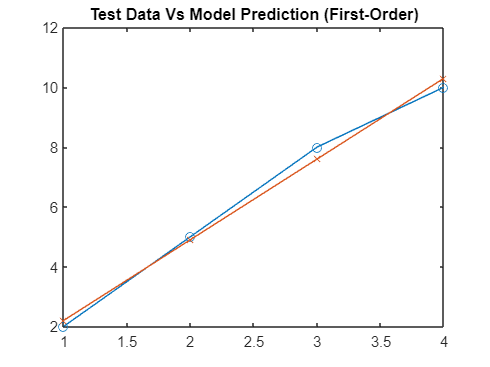

y_hat = X_aug*B;
plot(x,y,"-o"); title("Test Data Vs Model Prediction (First-Order)");
hold on;
plot(x,y_hat,"-x"); 

clc, close all; clear

x = [1 2 3 4]'

x =      1
     2
     3
     4


y = [2 5 8 10]'

y =      2
     5
     8
    10


X_aug = [x.^2,x,ones(4,1)] 

X_aug =      1     1     1
     4     2     1
     9     3     1
    16     4     1


X_trans = X_aug'

X_trans =      1     4     9    16
     1     2     3     4
     1     1     1     1


B = ((X_trans*X_aug)^(-1))*X_trans*y 

B =    -0.2500
    3.9500
   -1.7500


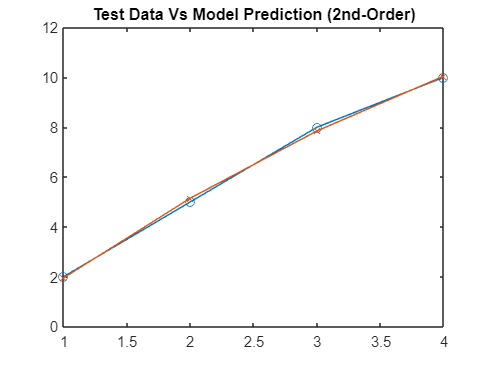

y_hat = X_aug*B;
plot(x,y,"-o"); title("Test Data Vs Model Prediction (2nd-Order)");
hold on;
plot(x,y_hat,"-x"); 

clc, close all; clear

x = [1 2 3 4]'

x =      1
     2
     3
     4


y = [2 5 8 10]'

y =      2
     5
     8
    10


X_aug = [x.^3,x.^2,x,ones(4,1)] 

X_aug =      1     1     1     1
     8     4     2     1
    27     9     3     1
    64    16     4     1


X_trans = X_aug'

X_trans =      1     8    27    64
     1     4     9    16
     1     2     3     4
     1     1     1     1


B = ((X_trans*X_aug)^(-1))*X_trans*y 

B =    -0.1667
    1.0000
    1.1667
   -0.0000


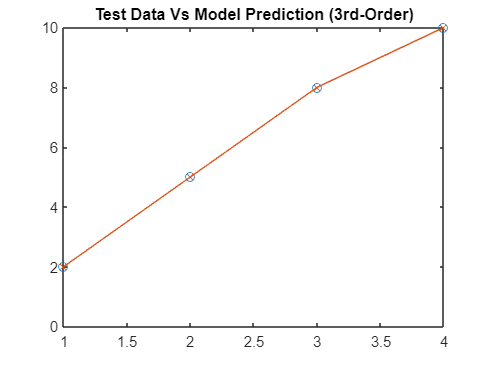

y_hat = X_aug*B;
plot(x,y,"-o"); title("Test Data Vs Model Prediction (3rd-Order)");
hold on;
plot(x,y_hat,"-x"); 

clc, close all; clear

filename = 'BTC-USD.xlsx';
% closes = readtable(filename)
y = xlsread(filename, 'F:F')

A = 	1.0e+04 *

    0.0998
    0.1022
    0.1044
    0.1155
    0.1013
    0.0902
    0.0909
    0.0911
    0.0903
    0.0908


x = [1:length(A)]'

x =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


X_aug = [x.^3,x.^2,x,ones(4,1)] 
X_trans = X_aug'
B = ((X_trans*X_aug)^(-1))*X_trans*y 
y_hat = X_aug*B;
plot(x,y,"-o"); title("Test Data Vs Model Prediction (3rd-Order)");
hold on;
plot(x,y_hat,"-x"); 